# Otsu's method

Global image threshold using Otsu's method

## Syntax

`T = graythresh(I)`

`[T,EM] = graythresh(I)`

## Description

`T ``= graythresh(I)` computes a global threshold `T` from grayscale image `I`, using Otsu's method . Otsu's method chooses a threshold that minimizes the intraclass variance of the thresholded black and white pixels. The global threshold `T` can be used with `imbinarize` to convert a grayscale image to a binary image.

`[T,EM] = graythresh(I)` also returns the effectiveness metric, `EM`.

Read a grayscale image into the workspace.

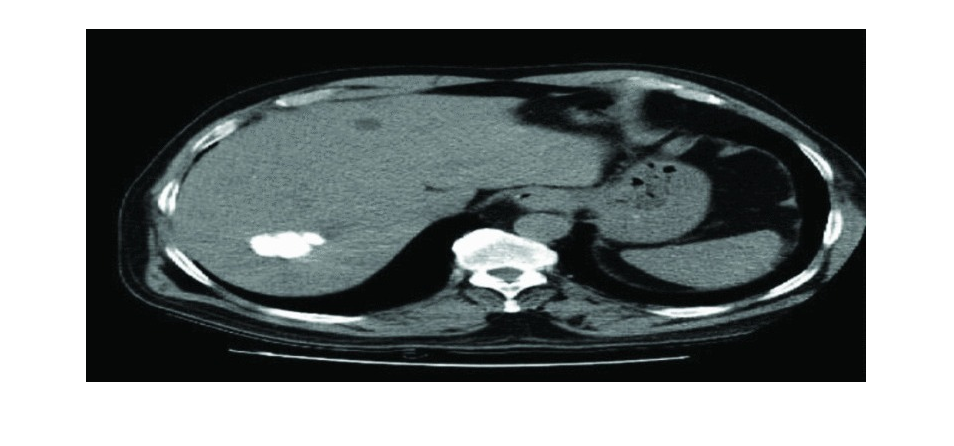

I = imread('E:\matlab_code\original.jpg');
imshow(I);

Calculate a threshold using graythresh. The threshold is normalized to the range [0, 1].


level = graythresh(I)

level = 0.2745

Convert the image into a binary image using the threshold.


BW = imbinarize(I,level);

Display the original image next to the binary image.

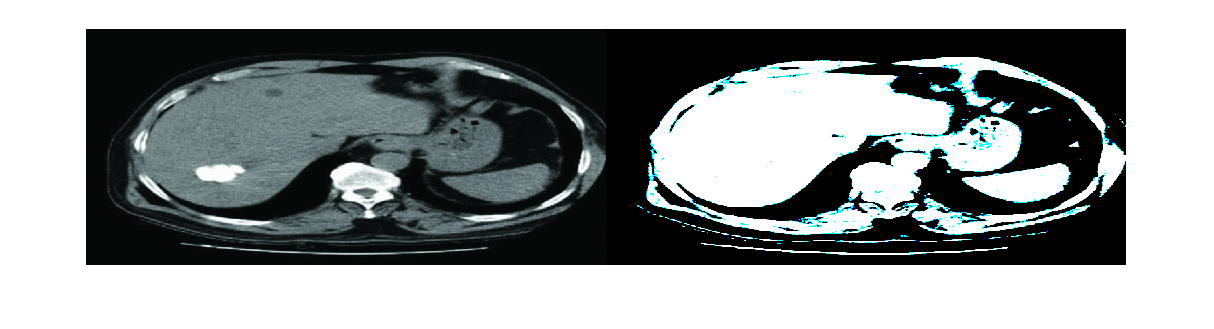

imshowpair(I,BW,'montage')